# Spline Subbotin


$$\begin{array}{l}
\textrm{Presupunem}\;\textrm{ca}\;\textrm{se}\;\textrm{da}\;\textrm{diviziunea}\;\Delta :a=t_0 <t_1 <\ldots<t_n =b;\textrm{fie}\;\textrm{nodurile}:\\
\tau_0 =t_0 ,\tau_{n+1} =t_n \\
\tau_i =\frac{1}{2}\left(t_i +t_{i-1} \right),i=1,\ldotsn\\
\textrm{Determinati}\;\textrm{un}\;\textrm{spline}\;\textrm{patratic}\;Q\in S_2^1 \left(\Delta \right)\;\textrm{care}\;\textrm{in}\;\textrm{nodurile}\;\textrm{date}\;\textrm{ia}\;\textrm{niste}\;\textrm{valori}\;\textrm{precise}:\\
Q\left(\tau_i \right)=y_i ,i=0\ldotsn+1\\
\textrm{Implementati}\;\textrm{metoda}\;\textrm{de}\;\mathrm{a}\;\textrm{calcula}\;\;\textrm{spline}-\textrm{ul}\;\textrm{in}\;\textrm{MATLAB}\ldotp 
\end{array}$$


## Rezolvare

### Solutia rudimentara (interpolarea cu $\tau_i$), conducand la un sistem supradeterminat

Dorim sa gasim un spline patratic cu nodurile $\tau_i$, deci trebuie rezolvat sistemul cu ecuatiile:

$Q_i \left(x\right)=c_{i,0} +c_{i,\;1} \left(x-\tau_i \right)+c_{i,2} {\left(x-\tau_i \right)}^2 ,i=1\ldotp \ldotp \ldotp n$,


$$Q_0 \left(x\right)=c_{0,0} +c_{0,1\;} \left(x-\tau_1 \right)+c_{0,2} {\left(x-\tau_1 \right)}^2$$


$\textrm{iar}\;\textrm{spline}-\textrm{ul}\;Q\;\textrm{va}\;\textrm{fi}\;\textrm{egal}\;\textrm{cu}\;{\left\lbrace Q_i \left(x\right),x\in \left\lbrack \tau_i ,\tau_{i+1} \right\rbrack \right\rbrace }_{i=0\ldotp \ldotp \ldotp n}$.


$$Q_i \left(\tau_i \right)=c_{i,0} ,\textrm{dar}\;Q_i \left(\tau_i \right)=y_i \Rightarrow c_{i,0} =y_i \ldotp$$


Fie $m_i =Q^{\prime } \left(\tau_i \right)={Q_i }^{\prime } \left(\tau_i \right)={Q_{i-1} }^{\prime } \left(\tau_i \right),i=1\ldotp \ldotp \ldotp n$.

Deoarece avem $Q_i \left(\tau_i \right)=y_i ,Q_i \left(\tau_{i+1} \right)=y_{i+1} ,{Q_i }^{\prime } \left(\tau_i \right)=m_i ,{Q_i }^{\prime } \left(\tau_{i+1} \right)=m_{i+1}$, putem aproxima polinomul $Q_i$ folosind interpolarea Hermite astfel:

$Q_i \left(x\right)=y_i +\left(x-\tau_i \right)m_i +{\left(x-\tau_i \right)}^2 \frac{y\left\lbrack \tau_i ,\tau_{i+1} \right\rbrack -m_i }{\tau_{i+1} -\tau_i }+{\left(x-\tau_i \right)}^2 \;\left(x-\tau_{i+1} \right)\frac{m_{i+1} +m_i -2\cdot y\left\lbrack \tau_i ,\tau_{i+1} \right\rbrack }{{\left(\tau_{i+1} -\tau_i \right)}^2 },i=1\ldotsn-1$ (1)

Deoarece avem 4 conditii, insa doar 3 coeficienti, este necesar ca coeficientul corespondent lui $x^3$ sa fie egal cu 0, deci:

$\frac{m_{i+1} +m_i -2\cdot y\left\lbrack \tau_i ,\tau_{i+1} \right\rbrack }{{\left(\tau_{i+1} -\tau_i \right)}^2 }=0\Leftrightarrow m_{i+1} +m_i =2\cdot y\left\lbrack \tau_i ,\tau_{i+1} \right\rbrack$  (2), avand n-1 ecuatii (i = 1...n-1)

Din (1) si din faptul ca $m_{i+1} +m_i =2\cdot y\left\lbrack \tau_i ,\tau_{I+1} \right\rbrack$ (demonstrat anterior), obtinem forma generala a polinomului $Q_i$:


$$Q_i \left(x\right)=y_i +\left(x-\tau_i \right)m_i +{\left(x-\tau_1 \right)}^2 \frac{m_{i+1} -m_i }{2\left(\tau_{i+1} -\tau_i \right)}\ldotp$$


Pentru capatul stang ($Q_0$), nu avem 4 conditii, vom avea doar 3: $Q_1 \left(\tau_1 \right)=y_1 ,{Q_1 }^{\prime } \left(\tau_1 \right)=m_1$, $Q_0 \left(\tau_0 \right)=y_0$, deci, prin interpolare Hermite:


$$Q_0 \left(x\right)=y_1 +\left(x-\tau_1 \right)\cdot m_1 +{\left(x-\tau_1 \right)}^2 \cdot \frac{m_1 -y\left\lbrack \tau_1 ,\tau_0 \right\rbrack }{\tau_0 -\tau_1 }$$


Deoarece $Q_0 \left(\tau_0 \right)=y_0$, rezulta:

$y_0 =y_1 +\left(\tau_0 -\tau_1 \right)m_1 +\left(\tau_0 -\tau_1 \right)\left(m_1 -y\left\lbrack \tau_1 ,\tau_0 \right\rbrack \right)\Rightarrow y_0 -y_1 =\left(\tau_0 -\tau_1 \right)\left(m_1 +m_1 -\frac{y_0 -y_1 }{\tau_0 -\tau_1 }\right)\Rightarrow 2\left(y_0 -y_1 \right)=2m_1 \left(\tau_0 -\tau_1 \right)\Rightarrow m_1 =y\left\lbrack \tau_1 ,\tau_0 \right\rbrack =y\left\lbrack \tau_0 ,\tau_1 \right\rbrack$. (3)

Pentru capatul drept ($Q_n$), nu avem 4 conditii la fel, ci doar 3: $Q_n \left(\tau_n \right)=y_n ,{Q_n }^{\prime } \left(\tau_n \right)=m_n ,Q_n \left(\tau_{n+1} \right)=y_{n+1}$, deci, prin interpolare Hermite:


$$Q_n \left(x\right)=y_n +\left(x-\tau_n \right)\cdot m_n +{\left(x-\tau_n \right)}^2 \cdot \frac{m_n -y\left\lbrack \tau_n ,\tau_{n+1} \right\rbrack }{\tau_{n+1} -\tau_n }$$


Deoarece $Q_n \left(\tau_{n+1} \right)=y_{n+1}$, rezulta:

$y_{n+1} =y_n +\left(\tau_{n+1} -\tau_n \right)m_n +\left(\tau_{n+1} -\tau_n \right)\left(m_n -\frac{y_{n+1} -y_n }{\tau_{n+1} -\tau_n }\right)\Rightarrow \ldots\Rightarrow m_n =y\left\lbrack \tau_n ,\tau_{n+1} \right\rbrack \ldotp$ (4)

Deci, din (2), (3) si (4), vom obtine n+1 ecuatii, dar avem n necunoscute, deci este supradeterminat?


$$\begin{array}{l}
m_1 =\frac{y_1 -y_0 }{\tau_1 -\tau_0 }=\frac{y_1 -y_0 }{\frac{t_1 +t_0 }{2}-t_0 }=2\frac{y_1 -y_0 }{t_1 -t_0 }\\
m_i +m_{i+1} =2\frac{y_{i+1} -y_i }{\tau_{i+1} -\tau_i }=2\frac{y_{i+1} -y_i }{\frac{t_{i+1} +t_i }{2}-\frac{t_i +t_{i-1} }{2}}=4\frac{y_{i+1} -y_i }{t_{i+1} -t_{i-1} },i=1\ldotp \ldotp \ldotp n-1\\
m_n =\frac{y_{n+1} -y_n }{\tau_{n+1} -\tau_n }=\frac{y_{n+1} -y_n }{t_n -\frac{t_n +t_{n-1} }{2}}=2\frac{y_{n+1} -y_n }{t_n -t_{n-1} }\ldotp 
\end{array}$$


Sistemul de rezolvat arata astfel:


$$\left\lbrack \begin{array}{cccccc}
t_1 -t_0  & 0 & 0 & \ldots & 0 & 0\\
t_2 -t_0  & t_2 -t_0  & 0 & \ldots & 0 & 0\\
0 & t_3 -t_1  & t_3 -t_1  & \ldots & 0 & 0\\
\vdots  & \vdots  & \vdots  & \ddots  & \vdots  & 0\\
0 & 0 & 0 & \ldots & t_n -t_{n-2}  & t_n -t_{n-2} \\
0 & 0 & 0 & \ldots & 0 & t_n -t_{n-1} 
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
m_1 \\
m_2 \\
m_3 \\
\vdots \\
m_{n-1} \\
m_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\left(y_1 -y_0 \right)\\
4\left(y_2 -y_1 \right)\\
4\left(y_3 -y_2 \right)\\
\vdots \\
4\left(y_n -y_{n-1} \right)\\
2\left(y_{n+1} -y_n \right)
\end{array}\right\rbrack$$


Observam ca liniile sistemului sunt liniar independente, deci sistemul nostru este supradeterminat si nu avem o solutie exacta.

### Solutia buna, interpoland pe$\left\lbrack t_i ,t_{i+1} \right\rbrack$ folosind valorile din $\tau_{i+1}$

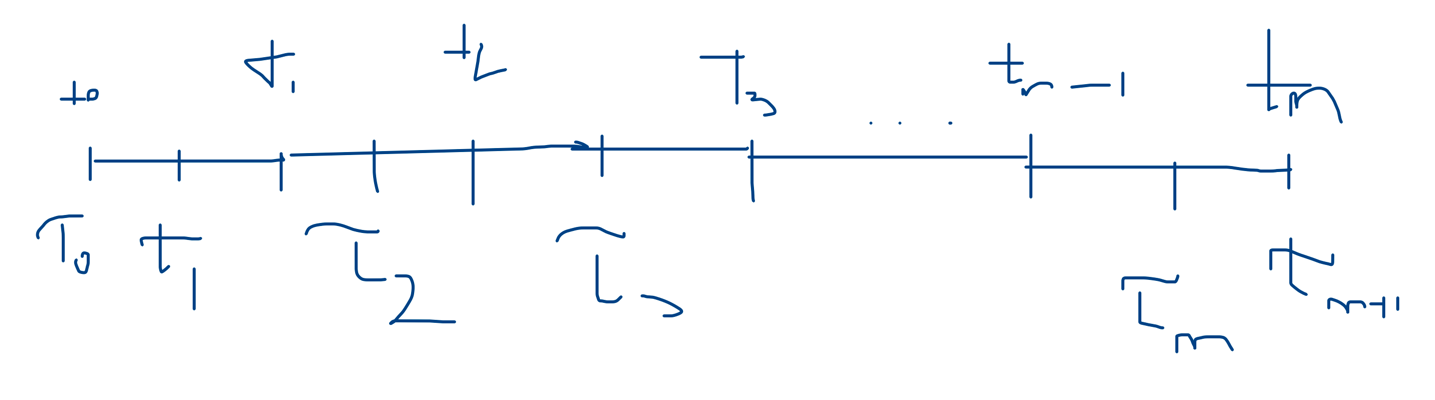


$$\tau_i =\frac{t_i +t_{i-1} }{2}$$


Dorim sa gasim un sistem asemanator:

$Q_i \left(x\right)=c_{i,0} +c_{i,\;1} \left(x-\tau_{i+1} \right)+c_{i,2} {\left(x-\tau_{i+1} \right)}^2 ,i=0\ldotp \ldotp \ldotp n\;\left(\textrm{de}\;\textrm{data}\;\textrm{aceasta}\;\textrm{alegem}\;\tau_{i+1} \;\textrm{pentru}\;\textrm{ca}\;\textrm{ca}\;\textrm{polinomul}\;\textrm{sa}\;\textrm{fie}\;\textrm{definit}\;\textrm{pe}\;\left\lbrack t_i ,t_{i+1} \right\rbrack ,\textrm{iar}\;\textrm{in}\;\textrm{intervalul}\;\textrm{acela}\;\textrm{se}\;\textrm{afla}\;\tau_{i+1} \right)$,

$\textrm{doar}\;\textrm{ca}\;\textrm{vom}\;\textrm{spline}-\textrm{ul}\;Q\;\textrm{care}\;\textrm{de}\;\textrm{data}\;\textrm{aceasta}\;\textrm{va}\;\textrm{fi}\;\textrm{egal}\;\textrm{cu}\;{\left\lbrace Q_i \left(x\right),x\in \left\lbrack t_i ,t_{i+1} \right\rbrack \right\rbrace }_{i=0\ldotp \ldotp \ldotp n-1}$.

Impunem lui $Q_i$ urmatoarele 3 conditii: ${{Q{\;}_i \left(\tau_{i+1} \right)=y_{i+1} ,{Q_i }^{\prime } \left(t_i \right)=m_i ,\;\;Q}_i }^{\prime } \left(t_{i+1} \right)=m_{i+1} ,i=0\ldotp \ldotp n-1$. Vom obtine, din interpolarea Lagrange a polinomului ${Q_i }^{\prime }$ (cu notatia $\left.\Delta t_i =t_{i+1} -t_i \right)$:

$\begin{array}{l}
{Q_i }^{\prime } \left(x\right)=m_i +\left(x-t_i \right)\frac{m_{i+1} -m_i }{\Delta t_i }=m_i +\left(x-t_i \right)\frac{m_{i+1} -m_i }{\Delta t_i }=m_I +x\frac{m_{i+1} -m_i }{\Delta t_i }-t_1 \frac{m_{i+1} -m_i }{\Delta t_i }=m_i +\left(x-\tau_{i+1} \right)\frac{m_{i+1} -m_i }{\Delta t_i }+\left(\tau_{i+1} -t_i \right)\frac{m_{i+1} -m_i }{\Delta t_i }\\
\;\;\;\;\;\;\;\;\;\;\;=m_i +{\left(x-\tau_{i+1} \right)}^{\prime } \frac{m_{i+1} -m_i }{\Delta t_i }+\frac{{\mathit{\mathbf{t}}}_{\mathit{\mathbf{i}}+1} -{\mathit{\mathbf{t}}}_{\mathit{\mathbf{i}}} }{2}\cdot \frac{m_{i+1} -m_i }{\Delta {\mathit{\mathbf{t}}}_{\mathit{\mathbf{i}}} }=\frac{m_{i+1} +m_i }{2}+\left(x-\tau_{i+1} \right)\frac{m_{i+1} -m_i }{\Delta t_i }
\end{array}$.

Integrand pe ${Q_i }^{\prime }$ (in raport cu $x-\tau_{i+1}$), obtinem:

$Q_i \left(x\right)=c+\left(x-\tau_{i+1} \right)\frac{m_{i+1} +m_i }{2}+\frac{{\left(x-\tau_{i+1} \right)}^2 }{2}\frac{m_{i+1} -m_i }{\Delta t_i }$.

Impunand conditia $Q_i \left(\tau_{i+1} \right)=y_{i+1}$ asupra ultimei ecuatii obtinute:

$Q_i \left(\tau_{i+1} \right)=c\Rightarrow c=y_{i+1} \Rightarrow Q_i \left(x\right)=y_{i+1} +\left(x-\tau_{i+1} \right)\frac{m_{i+1} +m_i }{2}+\frac{{\left(x-\tau_{i+1} \right)}^2 }{2}\frac{m_{i+1} -m_i }{\Delta t_i }\ldotp$ (+)

Deoarece am interpolat pe $t_i$, mai este necesara conditia: $Q_i \left(t_{i+1} \right)=Q_{i+1} \left(t_{i+1} \right),i=0\ldotp \ldotp n-2$. Vom obtine:


$$\begin{array}{l}
y_i +\left(t_{i+1} -\frac{t_i +t_{i+1} }{2}\right)\frac{m_{i+1} +m_i }{2}+{\left(t_{i+1} -\frac{t_i +t_{i+1} }{2}\right)}^2 \frac{m_{i+1} -m_i }{2\Delta t_i }=y_{i+1} +\left(t_{i+1} -\frac{t_{i+1} +t_{i+2} }{2}\right)\frac{m_{i+2} +m_{i+1} }{2}+{\left(t_{i+1} -\frac{t_{i+1} +t_{i+2} }{2}\right)}^2 \frac{m_{i+2} -m_{i+1} }{2\Delta t_{i+1} }\Leftrightarrow \\
\Leftrightarrow y_i +\frac{\Delta t_i \left(m_{i+1} +m_i \right)}{4}+\frac{\Delta t_i^2 \left(m_{i+1} -m_i \right)}{8\Delta t_i }=y_{i+1} +\frac{-\Delta t_{i+1} \left(m_{i+2} +m_{i+1} \right)}{4}+\frac{\Delta t_{i+1}^2 \left(m_{i+2} -m_{i+1} \right)}{8\Delta t_{i+1} }\Leftrightarrow \\
\Leftrightarrow y_i -y_{i+1} =\frac{-\Delta t_{i+1} \left(m_{i+2} +m_{i+1} \right)}{4}+\frac{\Delta t_{i+1} \left(m_{i+2} -m_{i+1} \right)}{8}-\frac{\Delta t_i \left(m_{i+1} +m_i \right)}{4}-\frac{\Delta t_i \left(m_{i+1} -m_i \right)}{8}\Leftrightarrow \\
\Leftrightarrow 8\left(y_i -y_{i+1} \right)=\Delta t_{i+1} \left(m_{i+2} -m_{i+1} -2m_{i+2} -2m_{i+1} \right)-\Delta t_i \left(m_{i+1} -m_i +2m_{i+1} +2m_i \right)\Leftrightarrow \\
\Leftrightarrow 8\left(y_i -y_{i+1} \right)=\Delta t_{i+1} \left(-m_{i+2} -3m_{i+1} \right)-\Delta t_i \left({3m}_{i+1} +m_i \right)\Leftrightarrow \\
\Leftrightarrow 8\left(y_{i+1} -y_i \right)=m_{i+2} \Delta t_{i+1} +{3m}_{i+1} \left(\Delta t_{i+1} +\Delta t_i \right)+m_i \Delta t_i \;,\textrm{pentru}\;i=0\ldotp \ldotp \ldotp n-2\;\left(1\right)
\end{array}$$


Pana in acest punct avem n-1 ecuatii, si n+1 necunoscute $\left(m_{i=0\ldotp \ldotp n} \right)$. Mai impunem conditiile in capete:


$$\begin{array}{l}
Q_0 \left(t_0 \right)=y_0 \Leftrightarrow y_1 +\left(t_0 -\frac{t_1 +t_0 }{2}\right)\frac{m_1 +m_0 }{2}+{\left(t_0 -\frac{t_1 +t_0 }{2}\right)}^2 \frac{m_1 -m_0 }{2\Delta t_0 }=y_0 \Leftrightarrow \frac{-\Delta t_0 \left(m_1 +m_0 \right)}{4}+\frac{\Delta t_0^2 \left(m_1 -m_0 \right)}{8\Delta t_0 }=y_0 -y_1 \Leftrightarrow \\
\Leftrightarrow \;{\Delta t}_0 \left(-2m_1 +-2m_0 +m_1 -m_0 \right)=8\left(y_0 -y_1 \right)\Leftrightarrow {3m}_0 \Delta t_0 +m_1 \Delta t_0 =8\left(y_1 -y_0 \right)\;\left(2\right)
\end{array}$$



$$\begin{array}{l}
Q_{n-1} \left(t_n \right)=y_{n+1} \Leftrightarrow y_n +\left(t_n -\frac{t_n +t_{n-1} }{2}\right)\frac{m_n +m_{n-1} }{2}+{\left(t_n -\frac{t_n +t_{n-1} }{2}\right)}^2 \frac{m_n -m_{n-1} }{2\Delta t_{n-1} }=y_{n+1} \Leftrightarrow \frac{\Delta t_{n-1} \left(m_n +m_{n-1} \right)}{4}+\frac{\Delta t_{n-1}^2 \left(m_n -m_{n-1} \right)}{8\Delta t_{n-1} }=y_{n+1} -y_n \Leftrightarrow \\
\Leftrightarrow \Delta t_{n-1} \left(2m_n +2m_{n-1} +m_n -m_{n-1} \right)=8\left(y_{n+1} -y_n \right)\Leftrightarrow 3m_n \Delta t_{n-1} +m_{n-1} \Delta t_{n-1} =8\left(y_{n+1} -y_n \right)\;\left(3\right)
\end{array}$$


Din (1), (2) si (3) avem n+1 ecuatii si n+1 necunoscute, deci putem ajunge la sistemul:

$\left\lbrack \begin{array}{cccccccc}
3\Delta t_0  & \Delta t_0  & 0 & 0 & \ldots & 0 & 0 & 0\\
\Delta t_0  & 3\left(\Delta t_1 +\Delta t_0 \right) & \Delta t_1  & 0 & \ldots & 0 & 0 & 0\\
0 & \Delta t_1  & 3\left(\Delta t_2 +\Delta t_1 \right) & \Delta t_2  & \ldots & 0 & 0 & 0\\
\vdots  & \vdots  & \vdots  & \vdots  & \ddots  & \vdots  & \vdots  & \vdots \\
0 & 0 & 0 & 0 & \ldots & \Delta t_{n-2}  & 3\left(\Delta t_{n-1} +\Delta t_{n-2} \right) & \Delta t_{n-1} \\
0 & 0 & 0 & 0 & \ldots & 0 & \Delta t_{n-1}  & 3\Delta t_{n-1} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
m_0 \\
m_1 \\
m_2 \\
\vdots \\
m_{n-1} \\
m_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
8\left(y_1 -y_0 \right)\\
8\left(y_2 -y_1 \right)\\
8\left(y_3 -y_2 \right)\\
\vdots \\
8\left(y_n -y_{n-1} \right)\\
8\left(y_{n+1} -y_n \right)
\end{array}\right\rbrack$.

## Implementare MATLAB

Acest sistem este tridiagonal, simetric si diagonal dominant (fiecare element de pe diagonala este de 3 ori suma pe linii / coloane). Rezolvam acest sistem in MATLAB:

function m=SolveSubbotinSystem(dt, y)
    A=3*diag([dt(1) dt(2:end)+dt(1:end-1) dt(end)]) + diag(dt, 1) + diag(dt, -1);
    b=8*(y(2:end)-y(1:end-1))';
    m=A\b;
end

Avand solutia sistemului, putem evalua spline-ul Subbotin folosind formula (+) cu urmatoarea functie in MATLAB:

function [S, tau, evalT]=EvalSubbotinSpline(t, y, x)
    dt=(t(2:end)-t(1:end-1));
    tau=[t(1) (t(1:end-1)+t(2:end))/2 t(end)]';
    m=SolveSubbotinSystem(dt, y);

    S=zeros(size(x));
    for i=1:length(x)
        if x(i)==t(end)
            S(i)=y(end);
        else
            poz=find(t>x(i),1)-1;
            X=x(i)-tau(poz+1);
            S(i)=y(poz+1) + X*(m(poz+1)+m(poz))/2 + X^2*(m(poz+1)-m(poz))/(2*dt(poz));
        end
    end

    evalT=zeros(size(t));
    evalT(1)=y(1);
    for i=2:length(t)-1
        X=t(i)-tau(i);
        evalT(i)=y(i) + X*(m(i)+m(i-1))/2 + X^2*(m(i)-m(i-1))/(2*dt(i-1));
    end
    evalT(end)=y(end);
end

Vom reprezenta grafic sistemul pentru a vizualiza spline-ul obtinut:

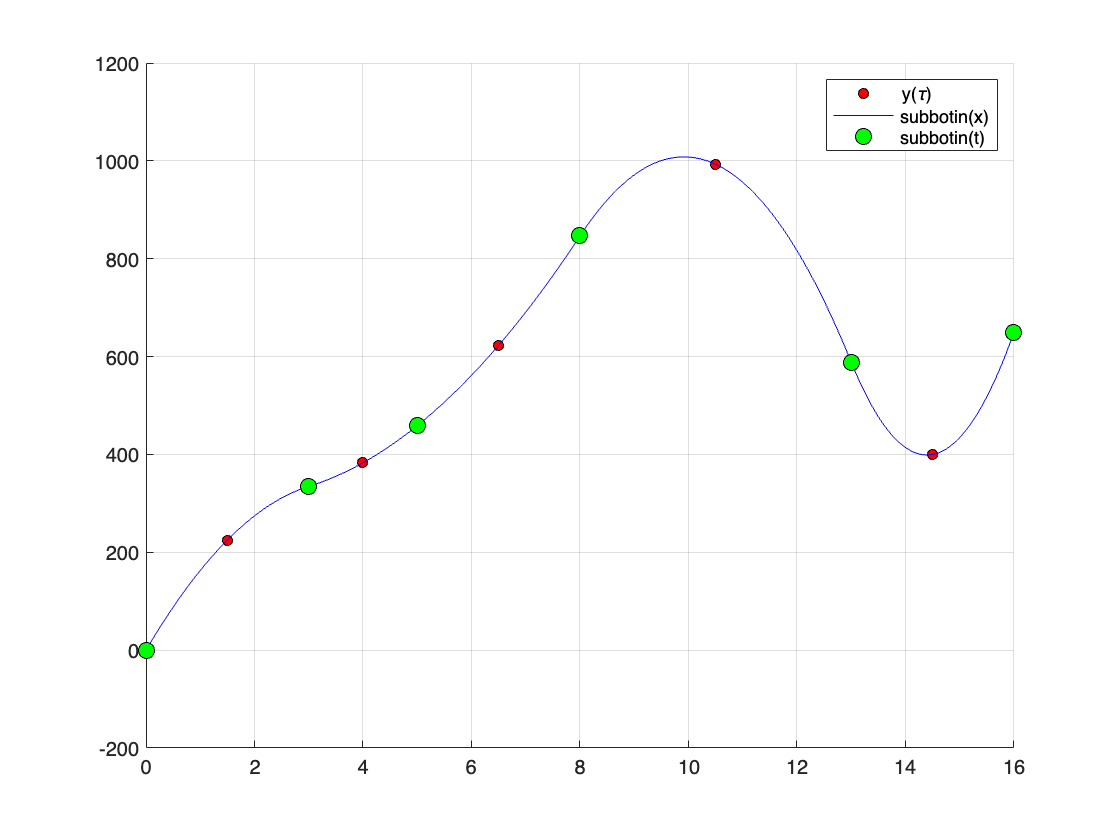

function VisualizeSubbotinSpline(t, y)
    clf; hold on; grid on;

    x=linspace(min(t),max(t),1000);
    [S, tau, evalT]=EvalSubbotinSpline(t,y,x);
    plot(tau, y, 'ok', 'markerfacecolor', 'r', 'markersize', 5);
    plot(x, S, 'b');
    plot(t, evalT, 'ok', 'markerfacecolor', 'g', 'markersize', 8);
    legend("y(\tau)", "subbotin(x)", "subbotin(t)");
end

nodes=[0 3 5 8 13 16];
values=[0  225  383  623  993 400 650];
VisualizeSubbotinSpline(nodes, values)